# TP1 de Traitement Numérique du Signal

# SCIENCES DU NUMERIQUE 1A

# Fevrier 2025 

# Aurélien VERBEKE (Groupe G)

## 2.1 - Représentation temporelle

#### Q1

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%PARAMETRES GENERAUX
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A = 1;        %amplitude du cosinus
f0 = 1100;       %fréquence du cosinus en Hz
T0 = 1/f0;       %période du cosinus en secondes
N = 90;        %nombre d'échantillons souhaités pour le cosinus
Fe = 10000;       %fréquence d'échantillonnage en Hz
Te = 1/Fe;       %période d'échantillonnage en secondes

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GENERATION DU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Définition de l'échelle temporelle d'échantillonage
temps=[0:N-1]*Te;
%Génération de N échantillons de cosinus à la fréquence f0
x=A*cos(2*pi*f0*temps);

#### Q2

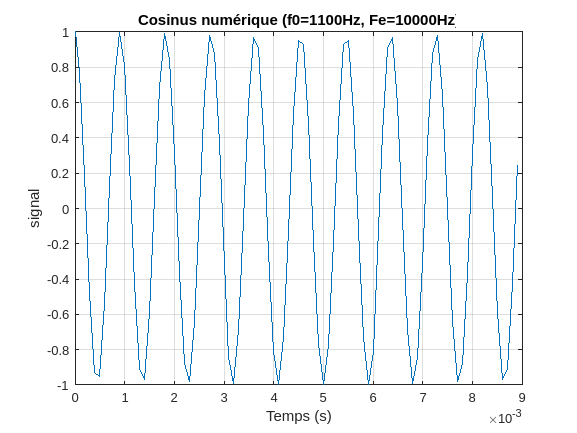

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TRACE DU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Tracé avec une échelle temporelle en secondes
%des labels sur les axes et un titre (utilisation de xlabel, ylabel et
%title)
figure
plot(temps, x);
grid
xlabel('Temps (s)')
ylabel('signal')
title(['Cosinus numérique (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz)']);

On lit bien $T_0 \approx 9*10^{-4} \; s$ donc $f_0 \approx 1100 \, \text{Hz}$ et $A = 1$.

#### Q3

% On abaisse la fréquence d'échantillonage tq Fe<2*f0
Fe_sous_echantillonne = 1000;       %fréquence d'échantillonnage en Hz
Te_sous_echantillonne = 1/Fe_sous_echantillonne;       %période d'échantillonnage en secondes

#### Q4

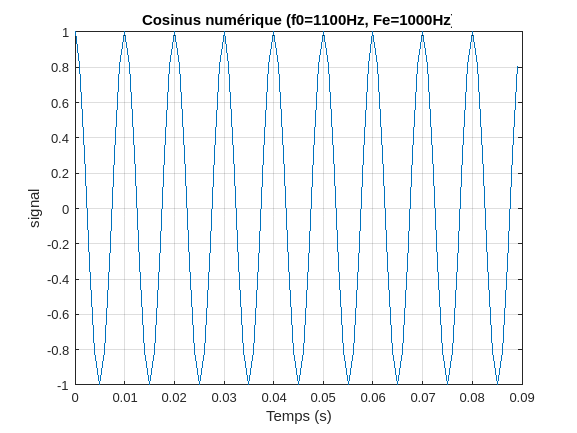

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GENERATION DU NOUVEAU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Définition de l'échelle temporelle d'échantillonage
temps_sous_echantillonne = [0:N-1]*Te_sous_echantillonne;
%Génération de N échantillons de cosinus à la fréquence f0
x_sous_echantillonne = A*cos(2*pi*f0*temps_sous_echantillonne);

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TRACE DU NOUVEAU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Tracé avec une échelle temporelle en secondes
%des labels sur les axes et un titre (utilisation de xlabel, ylabel et
%title)
figure
plot(temps_sous_echantillonne, x_sous_echantillonne);
grid
xlabel('Temps (s)')
ylabel('signal')
title(['Cosinus numérique (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe_sous_echantillonne) 'Hz)']);

On lit $T_0 \approx 10^{-2} \; \text{s}$ donc $f_0 \approx 100 \, \text{Hz}$ et $A = 1$, ce qui est erroné.

On n'a pas respecté la condition de Shannon.

On récupère en fait $F_e-f_0$.

## 2.2 - Représentation fréquentielle

### 2.2.1 - TFD

#### Q1

D'après la condition de Shannon, on ne peut mesurer que des fréquences jusqu'à $\frac{F_e}{2}$

Comme la fréquence d'échantillonage vaut $F_e$, la distribution fréquentielle sur $[-\frac{F_e}{2} \; ; \; 0]$ sera observée sur $[0 \; ; \; \frac{F_e}{2}]$

Aussi, le signal est réel donc la partie négative est obtenue par symétrie de la partie positive.

#### Q2

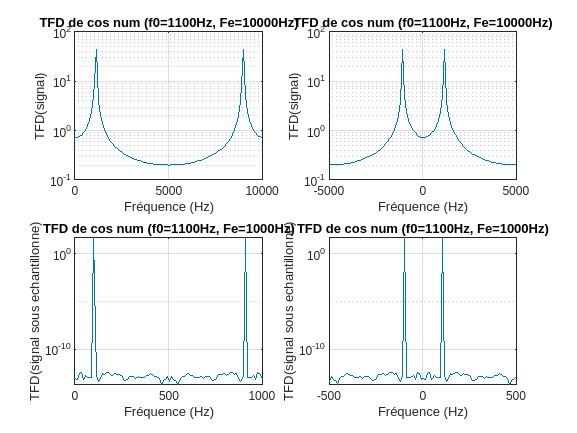

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%CALCUL DE LA TRANSFORMEE DE FOURIER NUMERIQUE (TFD) DU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
X = abs(fft(x));
X_centre = fftshift(X);

X_sous_echantillonne = abs(fft(x_sous_echantillonne));
X_sous_echantillonne_centre = fftshift(X_sous_echantillonne);

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TRACE DE LA TRANSFORMEE DE FOURIER NUMERIQUE (TFD) DU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure

subplot(2,2,1)
semilogy(linspace(0, Fe, N), X)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz)']);

subplot(2,2,2)
semilogy(linspace(-Fe/2, Fe/2, N), X_centre)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz)']);

subplot(2,2,3)
semilogy(linspace(0, Fe_sous_echantillonne, N), X_sous_echantillonne)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal sous echantillonne)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe_sous_echantillonne) 'Hz)']);

subplot(2,2,4)
semilogy(linspace(-Fe_sous_echantillonne/2, Fe_sous_echantillonne/2, N), X_sous_echantillonne_centre)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal sous echantillonne)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe_sous_echantillonne) 'Hz)']);

On ne retrouve que la fréquence du cosinus qui respecte la condition de Shannon (meme explication qu'à la question 2.1.4).

#### Q3

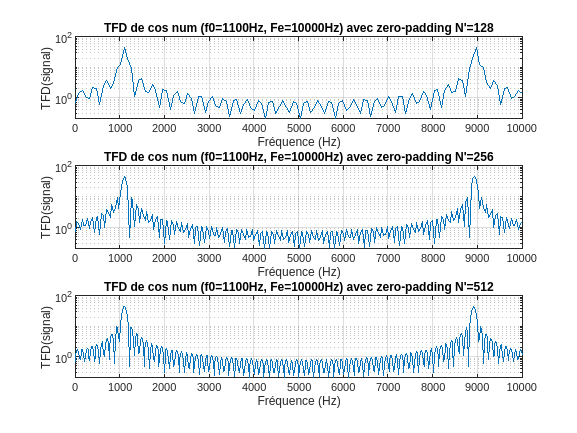

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%CALCUL DE LA TRANSFORMEE DE FOURIER NUMERIQUE (TFD) DU COSINUS NUMERIQUE
%AVEC ZERO-PADDING
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure

N_ZP = 128;
X_ZP_128 = abs(fft(x, N_ZP));
subplot(3, 1, 1)
semilogy(linspace(0, Fe, N_ZP), X_ZP_128)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz) avec zero-padding N''=128']);

N_ZP=256;
X_ZP_256 = abs(fft(x, N_ZP));
subplot(3, 1, 2)
semilogy(linspace(0, Fe, N_ZP), X_ZP_256)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz) avec zero-padding N''=256']);

N_ZP=512;
X_ZP_512 = abs(fft(x, N_ZP));
subplot(3, 1, 3)
semilogy(linspace(0, Fe, N_ZP), X_ZP_512)
grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz) avec zero-padding N''=512']);

La signal de base reste le meme, on a juste amélioré la précision de la TFD.

#### Q4

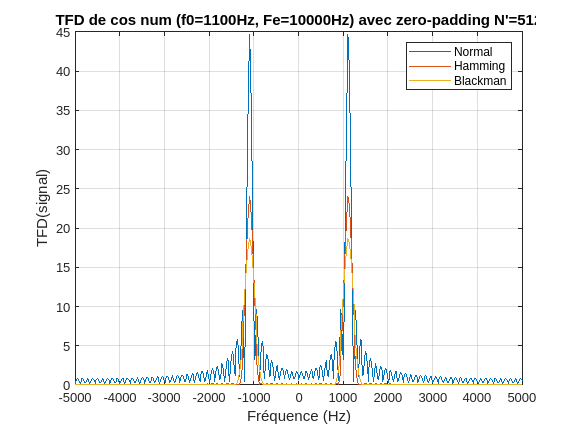

figure

N_ZP=512;

plot(linspace(-Fe/2, Fe/2, N_ZP), fftshift(abs(X_ZP_512)))
hold on

w=window(@hamming,length(x));
X_ZP_512_hamming = fftshift(abs(fft(x.*w', N_ZP)));
plot(linspace(-Fe/2, Fe/2, N_ZP), X_ZP_512_hamming)

w=window(@blackman,length(x));
X_ZP_512_blackman = fftshift(abs(fft(x.*w', N_ZP)));
plot(linspace(-Fe/2, Fe/2, N_ZP), X_ZP_512_blackman)

grid
xlabel('Fréquence (Hz)')
ylabel('TFD(signal)')
title(['TFD de cos num (f0=' num2str(f0) 'Hz, Fe=' num2str(Fe) 'Hz) avec zero-padding N''=512']);
legend('Normal', 'Hamming', 'Blackman')

L'intéret est de tronquer le signal et d'obtenir différentes représentations de la transformée de Fourier.

Ainsi, on peut y lire différentes informations sur le signal.

### 2.2.2 - DSP

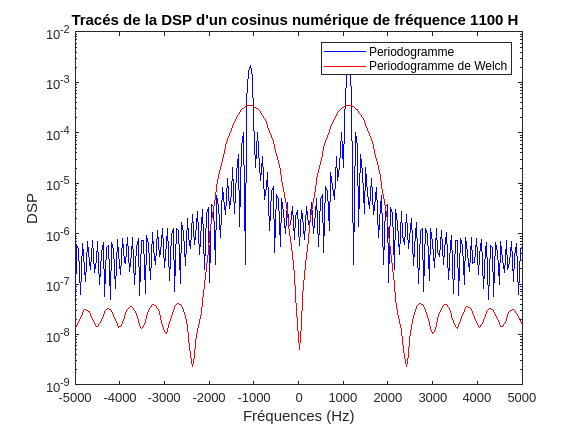

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%CALCUL DE LA DENSITE SPECTRALE DE PUISSANCE (DSP) DU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Estimation par périodogramme
Sx_periodogramme = periodogram(x, [], [], Fe, 'twosided');

%Estimation par périodogramme de Welch
Sx_Welch = pwelch(x, [],[],[],Fe,'twosided');

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TRACE DE LA DENSITE SPECTRALE DE PUISSANCE (DSP) DU COSINUS NUMERIQUE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Tracés superposés sur une même figure en utilisant fftshift
%Avec une échelle fréquentielle en Hz
%des labels sur les axes, un titre, une légende
figure

semilogy(linspace(-Fe/2, Fe/2, length(Sx_periodogramme)), fftshift(Sx_periodogramme),'b')
hold on
semilogy(linspace(-Fe/2, Fe/2, length(Sx_Welch)), fftshift(Sx_Welch),'r')

legend('Periodogramme','Periodogramme de Welch')
xlabel('Fréquences (Hz)')
ylabel('DSP')
title('Tracés de la DSP d''un cosinus numérique de fréquence 1100 Hz');

On retrouve toujours bien la fréquence $f_0$.

On utilisant le périodogramme de Welch, on réduit la variance d'estimation de la DSP.

## 2.3 - Autocorrélation

#### Q1

On a $SNR=10\log\left(\frac{P_{sig}}{P_{bruit}}\right)$

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%CALCUL ET TRACE DE LA FONCTION D'AUTOCORRELATION DU COSINUS BRUITE AVEC LE
%BON SNR
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   
SNR = 0; %dB

%Calcul de la puissance du signal
P_signal = mean(abs(x).^2);
%Calcul de la puissance du bruit pour obtenir le SNR souhaité
P_bruit = P_signal*(10^(SNR/10));

%Génération du bruit gaussien à la puissance Pb
bruit=sqrt(P_bruit)*randn(1,length(x));

#### Q2

%Ajout du bruit sur le signal
x_bruite=x+bruit;

%Calcul de la fonction d'autocorrélation du signal bruite
%attention pas le 1/N quand on utilise xcorr => à rajouter
Rx=(1/length(x_bruite))*xcorr(x_bruite); 

#### Q3

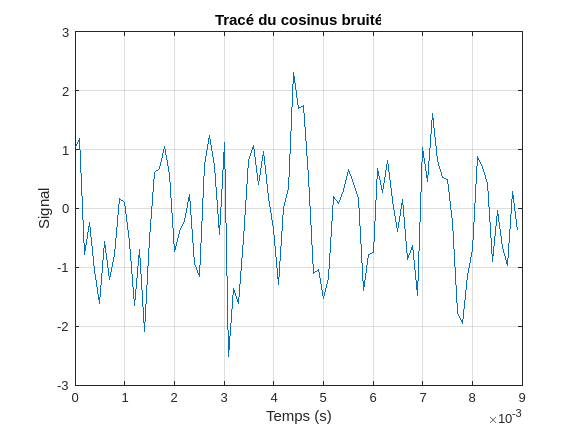

%Tracé du signal bruité avec une échelle temporelle en secondes
figure
plot(temps, x_bruite)
grid
xlabel('Temps (s)')
ylabel('Signal')
title('Tracé du cosinus bruité');

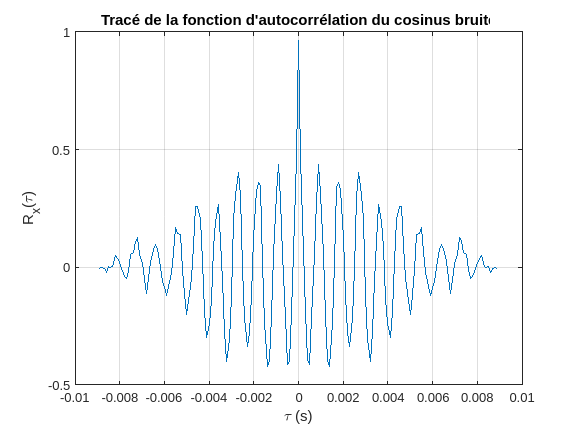

%Tracé de la fonction d'autocorrélation du signal bruite avec une échelle 
%temporelle en secondes
figure
echelle_tau=[-(N-1)*Te:Te:(N-1)*Te];
plot(echelle_tau, Rx)
grid
xlabel('\tau (s)')
ylabel('R_x(\tau)')
title('Tracé de la fonction d''autocorrélation du cosinus bruité');

#### Q4

C'est l'estimateur biaisé qui a été utilisé.

#### Q5

Ils ont la méme puissance moyenne.

#### Q6

La puissance du signal.

#### Q7

$R_x(0)=1$ donc $P=1$ donc $<|x|^2>=1$